Controllo se è rimasta aperta la porta seriale

if( exist('STM32_ser') );
    delete(STM32_ser);
    clear STM32_ser;
end

Connetto alla seriale

porte_libere = serialportlist("available")

porte_libere = "COM6"

STM32_ser = serialport(porte_libere(end), 1000000, Timeout=2);
configureTerminator(STM32_ser,"CR");

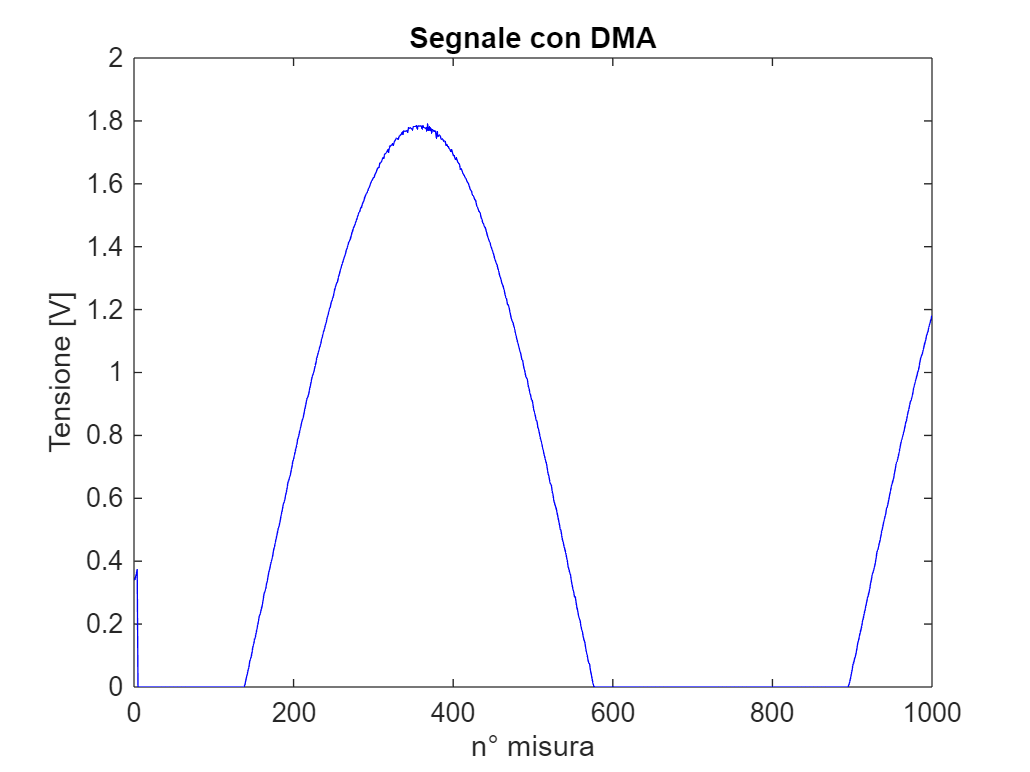

buff_size = 1000;
f = figure(1);

while 1
    if(STM32_ser.NumBytesAvailable > 1000)
        buff_data = STM32_ser.read(1000,'uint16');
        buff_data = buff_data ./ 2^16 * 3.3;

        figure(1)
        plot(1:1000, buff_data, 'b-')
        title("Segnale con DMA");
        xlabel("n° misura");
        ylabel("Tensione [V]");
        ylim([0,2]);
        drawnow
    end
end